# **Grid Codes Definitions for Voltage/Frequency Ride Through**

## **Load Grid Code Definitions**

Voltage/frequency grid codes have both event time and voltage/frequency definitions. Voltage conditions are typically given in per unit (PU) measurements. Codes, such as PRC-024, dictate under what conditions a generator have to remain grid connected and have only a single bound. Other codes, such as IEEE 1547-2018, have both mandatory bounds and optional bounds. These codes are definted in the "gridCodeDefinitions" file.

gridCodeDefinitions

## **View Mandatory Voltage/Frequency Requirements**

Each voltage/frequency ride though grid code has a post-fault time condition and both a high/low voltage and frequency condition. Most codes only have "mandatory" requirements where a system must be either connected or trip.

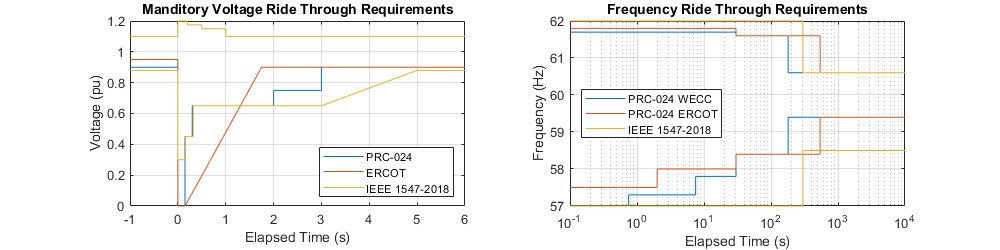

plotMandatoryCodes(IEEE1547,PRC024,ERCOT)

## IEEE 1547-2018 Manditory vs. Optional Ride Through

This plot compares the regions of the IEEE 1547-2018 standard. In the must ride through region, the DER cannot trip. Outside the optional bounds, the DER must trip from the grid. Between the must ride through and the shall trip region, the DER can trip or remain connected at its discression.

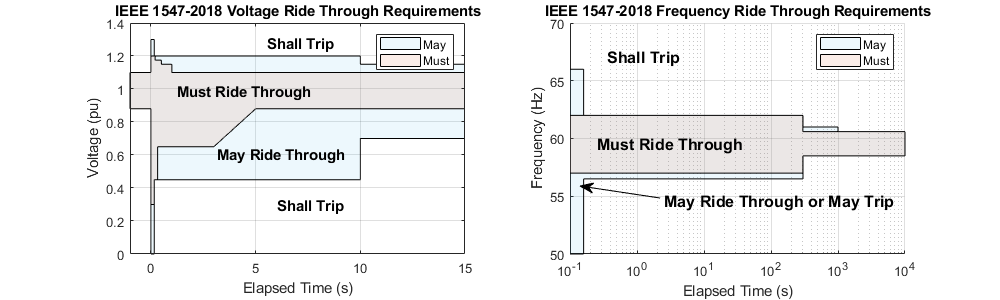

plotIEEE1547(IEEE1547)

## IEEE 1547-2018 Voltage/Frequency Chart

Another method of visualization of IEEE1547 or other grid codes is to plot both on the same axes. Live data can be streamed on this type of visualization to see if any events occur on the grid connected system.

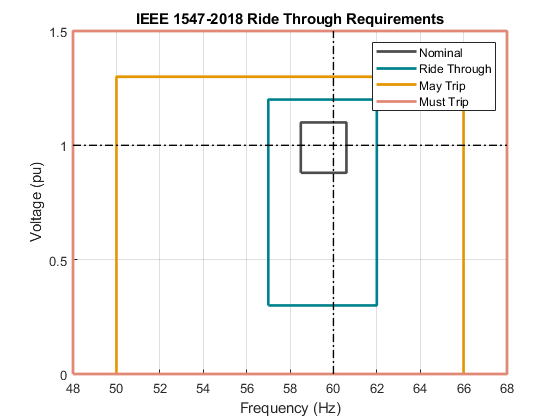

plot2D_IEEE1547(IEEE1547)

## Appendix - Plotting Functions

function plotMandatoryCodes(IEEE1547,PRC024,ERCOT)

figure('Position',[0 0 1000 250]); subplot(1,2,1)
plot([PRC024.LVRT.T NaN PRC024.HVRT.T],[PRC024.LVRT.V NaN PRC024.HVRT.V]); hold on;
plot([ERCOT.LVRT.T NaN ERCOT.HVRT.T],[ERCOT.LVRT.V NaN ERCOT.HVRT.V]);
plot([IEEE1547.mustLVRT.T NaN IEEE1547.mustHVRT.T],[IEEE1547.mustLVRT.V NaN IEEE1547.mustHVRT.V]); hold off;

legend('PRC-024','ERCOT','IEEE 1547-2018','Location','southeast')
xlim([-1 6]); grid on
title('Manditory Voltage Ride Through Requirements'); xlabel('Elapsed Time (s)'); ylabel('Voltage (pu)')

subplot(1,2,2)
semilogx([PRC024.WECC.LFRT.T NaN PRC024.WECC.HFRT.T],[PRC024.WECC.LFRT.F NaN PRC024.WECC.HFRT.F]); hold on;
semilogx([PRC024.ERCOT.LFRT.T NaN PRC024.ERCOT.HFRT.T],[PRC024.ERCOT.LFRT.F NaN PRC024.ERCOT.HFRT.F]);
semilogx([IEEE1547.mustLFRT.T NaN IEEE1547.mustHFRT.T],[IEEE1547.mustLFRT.F NaN IEEE1547.mustHFRT.F]);

legend('PRC-024 WECC','PRC-024 ERCOT','IEEE 1547-2018','Location','west')
xlim([0.1 10000]); grid on
title('Frequency Ride Through Requirements'); xlabel('Elapsed Time (s)'); ylabel('Frequency (Hz)');

end

function plotIEEE1547(IEEE1547)

figure('Position',[0 0 1000 300]); subplot(1,2,1);
fillLVRT_T = [IEEE1547.mayLVRT.T fliplr(IEEE1547.mayHVRT.T)];   fillLVRT_V = [IEEE1547.mayLVRT.V fliplr(IEEE1547.mayHVRT.V)];
fill(fillLVRT_T,fillLVRT_V,[0.3010    0.7450    0.9330],'FaceAlpha',0.1); hold on;

fillLVRT_T = [IEEE1547.mustLVRT.T fliplr(IEEE1547.mustHVRT.T)]; fillLVRT_V = [IEEE1547.mustLVRT.V fliplr(IEEE1547.mustHVRT.V)];
fill(fillLVRT_T,fillLVRT_V,[0.8500    0.3250    0.0980],'FaceAlpha',0.1); hold off;

legend('May','Must'); xlim([-1 15]); grid on
title('IEEE 1547-2018 Voltage Ride Through Requirements'); xlabel('Elapsed Time (s)'); ylabel('Voltage (pu)')

annotation('textbox',[0.17 0.64 0.19 0.1],'String',{'Must Ride Through'},'LineStyle','none','FontWeight','bold','FontSize',11);
annotation('textbox',[0.21 0.43 0.28 0.1],'String',{'May Ride Through'},'LineStyle','none','FontWeight','bold','FontSize',11);
annotation('textbox',[0.27 0.26 0.2 0.1],'String',{'Shall Trip'},'LineStyle','none','FontWeight','bold','FontSize',11);
annotation('textbox',[0.26 0.8 0.2 0.1],'String',{'Shall Trip'},'LineStyle','none','FontWeight','bold','FontSize',11);

subplot(1,2,2); 
hold on; set(gca,'XScale','log')
lowRemove = IEEE1547.mayLFRT.T > 0;     highRemove = IEEE1547.mayHFRT.T > 0;
fillLFRT_T = [IEEE1547.mayLFRT.T(lowRemove) fliplr(IEEE1547.mayHFRT.T(highRemove))];
fillLFRT_F = [IEEE1547.mayLFRT.F(lowRemove) fliplr(IEEE1547.mayHFRT.F(highRemove))];
patch(fillLFRT_T,fillLFRT_F,[0.3010    0.7450    0.9330],'FaceAlpha',0.1);

lowRemove = IEEE1547.mustLFRT.T > 0;    highRemove = IEEE1547.mustHFRT.T > 0;
fillLFRT_T = [IEEE1547.mustLFRT.T(lowRemove) fliplr(IEEE1547.mustHFRT.T(highRemove))]; 
fillLFRT_F = [IEEE1547.mustLFRT.F(lowRemove) fliplr(IEEE1547.mustHFRT.F(highRemove))];
patch(fillLFRT_T,fillLFRT_F,[0.8500    0.3250    0.0980],'FaceAlpha',0.1); hold off;

legend('May','Must'); xlim([0.1 10000]); grid on;
title('IEEE 1547-2018 Frequency Ride Through Requirements'); xlabel('Elapsed Time (s)'); ylabel('Frequency (Hz)')

annotation('textbox',[0.59 0.47 0.19 0.1],'String',{'Must Ride Through'},'LineStyle','none','FontWeight','bold','FontSize',12);
annotation('textbox',[0.657 0.28 0.28 0.1],'String',{'May Ride Through or May Trip'},'LineStyle','none','FontWeight','bold','FontSize',12);
annotation('textbox',[0.6 0.76 0.2 0.1],'String',{'Shall Trip'},'LineStyle','none','FontWeight','bold','FontSize',12);
annotation('arrow',[0.66 0.58],[0.34 0.38]);

end

function plot2D_IEEE1547(IEEE1547)

figure; hold on;

plot([58.5 60.6 60.6 58.5 58.5],[0.88 0.88 1.1 1.1 0.88],'Color',[0.2980    0.2980    0.2980],'LineWidth',2);
plot([IEEE1547.mustLFRT.F(3) IEEE1547.mustHFRT.F(3) IEEE1547.mustHFRT.F(3) IEEE1547.mustLFRT.F(3) IEEE1547.mustLFRT.F(3)],...
    [IEEE1547.mustLVRT.V(3) IEEE1547.mustLVRT.V(3) IEEE1547.mustHVRT.V(3) IEEE1547.mustHVRT.V(3) IEEE1547.mustLVRT.V(3)],'Color',[0    0.5098    0.5569],'LineWidth',2);
plot([IEEE1547.mayLFRT.F(3) IEEE1547.mayHFRT.F(3) IEEE1547.mayHFRT.F(3) IEEE1547.mayLFRT.F(3) IEEE1547.mayLFRT.F(3)],...
    [IEEE1547.mayLVRT.V(3) IEEE1547.mayLVRT.V(3) IEEE1547.mayHVRT.V(3) IEEE1547.mayHVRT.V(3) IEEE1547.mayLVRT.V(3)],'Color',[0.8941    0.5882    0],'LineWidth',2);
plot([48 68 68 48 48],[0 0 1.5 1.5 0],'Color',[0.8824    0.5333    0.4627],'LineWidth',2);
plot([60 60],[0 1.5],'LineStyle','-.','LineWidth',1,'Color','k');
plot([48 68],[1 1],'LineStyle','-.','LineWidth',1,'Color','k');

hold off; grid on;
xlim([48 68]);
ylim([0 1.5]);
xlabel('Frequency (Hz)'); ylabel('Voltage (pu)');
title('IEEE 1547-2018 Ride Through Requirements')
legend('Nominal','Ride Through','May Trip','Must Trip')

end